# EE-414 Speech Processing Lab

#  Lab-2

## Aim 

#### ● To understand the difference between stationary and non-stationary signals.

#### ● To get a feel about the non stationary nature of speech signals. 

#### ● To understand the limitations of Fourier transform in case of non-stationary signals.

## Introduction:

Signals are physical quantities which are measureable and Systems are physical entities which produce these signals. There are various categories under which signals can be classified such as: periodic/aperiodic, deterministic/stochastic, continuous/discrete etc. However in conventional signal processing, the stationary/non-stationary category of classification is not widely used, whereas this is of utmost importance in the case of speech signal processing. Speech signals traditionally are non-stationary signals, hence the techniques and concepts used while working with speech signals will be different as compared to conventional signal processing.

## Stationary vs non-stationary signals and the nature of speech signals:

Stationary signals means that the frequency/spectral content of the signal does not change with respect to time. Whereas in non-stationary waves, such properties changes with respect to time. Speech signals are non-stationary, hence different approaches are used to analyse and work with speech signals. For eg. a sine wave of given frequency is a stationary wave as its frequency is constant however its amplitude varies with time, therefore frequency content should only be checked if you want to check if a signal is stationary or not.

## A. Generation of a singletone sine wave and its spectrum.

- Generate a 10 Hz sine wave sampled at 1000 Hz sampling frequency and for a duration of 1 sec for this problem. 

### Theory:

A sine wave of a given frequency is a stationary signal, where the frequency content of the signal does not change with time (eventhough amplitude varies with time). In time domain the signal has its amplitude varying with time, whereas in the frequency spectrum, there will be a signal frequency impulse, thus proving the fact that the spectral properties infact do not change with respect to time.

Mathematically, a singleton sine wave is written as : $x(t) = A\cos(\omega t+\phi), \;\; t\in \mathbb{R}$, where $A$ is amplitude, $\omega$ is frequency and $\phi$ is phase

### Procedure:

We will create a sinewave using the inbuilt matlab command *sin(), *where we specify the frequency within the brackets (here we are taking A=1 and Phase=0). Since the specified frequency is constant throughout the whole time duration, the sine wave is a stationary signal. We take a large enough sampling frequency (obviously greater than twice the max frequency of the signal) so that we get a smoother and precise sine wave curves. We then plot this created sine wave with respect to time to get the time domain plot of the singleton sine wave.

We get frequency spectrum by using inbuilt *fft() *function, and also specifying nearest power of 2 for the length of signal to compute the N-point FFT. We are only taking half of the spectrum due to symmetry nature. Here we will see a peak at 10 hz in the spectrum.

### Code and Plots:

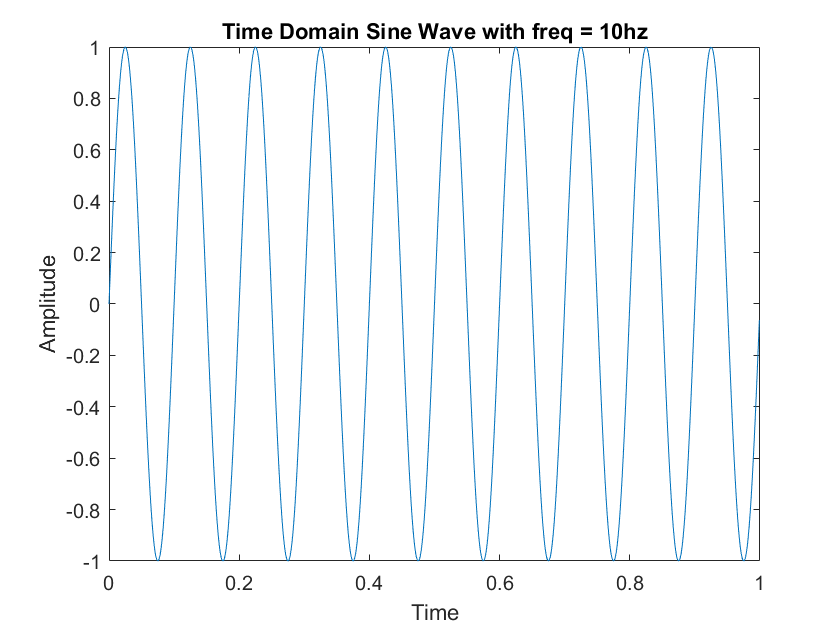

fs = 1000; % Sampling frequency (Hz) (Given)
step = 1/fs; % Incremental Step
timeDuration = 1; % Total time duration of sine wave (Given)
t = (0:step:timeDuration-1/fs); % Time interval 
freq = 10; % Frequency (Hz) (Given)

sineWave = sin(2*pi*freq*t);

plot_signal(t, sineWave,'Time', 'Amplitude', ['Time Domain Sine Wave with freq = ', num2str(freq), 'hz']); % Plotting time domain plot

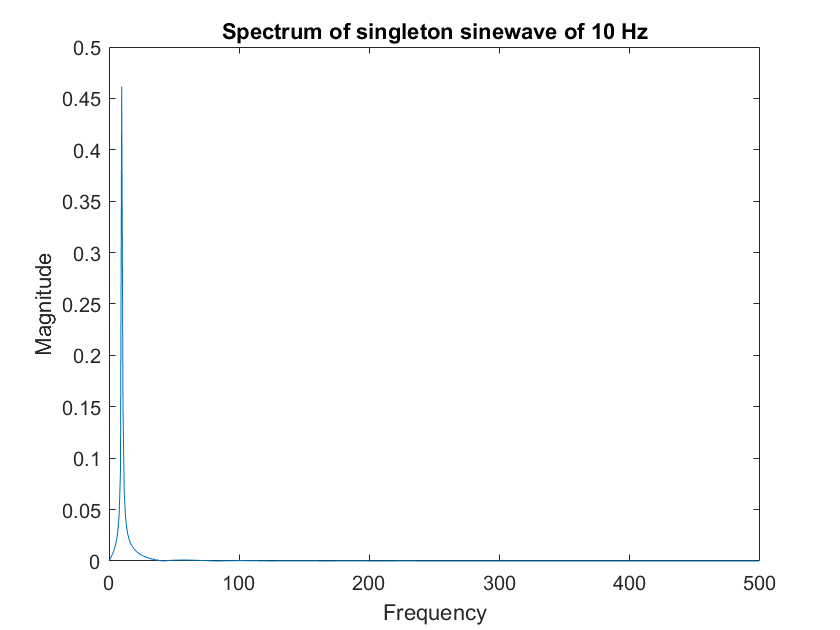

plot_spectrum(sineWave, fs, 'Spectrum of singleton sinewave of 10 Hz');

## B. Generation of a multitone sine wave and its spectrum

-  Generate a multitone sine wave composed of 10, 50 and 100 Hz frequency components. Use a sampling frequency of 1000Hz and a wave of duration 1 sec for the problem. 

### Theory:

Here, there are multiple frequency components are present however, these frequency components do not change with respect to time, hence these are still considered as stationary signals. Therefore this multitone sine wave consisting of different frequency components of 10 Hz, 50 Hz, 100 Hz is a stationary signal.

Mathematically given as:

 

Here A1 = A2 = A3 = 1, $\omega_1 =10\;\textrm{Hz}$, $\omega_2 =50\;\textrm{Hz}$, $\omega_3 =100\;\textrm{Hz}$, $\varphi_1 =\varphi_{2\;} =\varphi_3 =0$

### Procedure:

We will add up different sine waves of different frequencies, so that we get an overall wave of different frequencies. We will take a very large sampling frequency (1000 Hz) compared to the largest frequency present (100 Hz), to get a better time domain plot. We will observe a much more complex curve as compared to simple sine wave plot.

We take N-Point FFT of this multitone sine wave using inbuilt *fft() *function to observe its spectrum. We will now see peaks at 10 Hz, 50 Hz and 100 Hz in the frequency spectrum.

### Code and Plots:

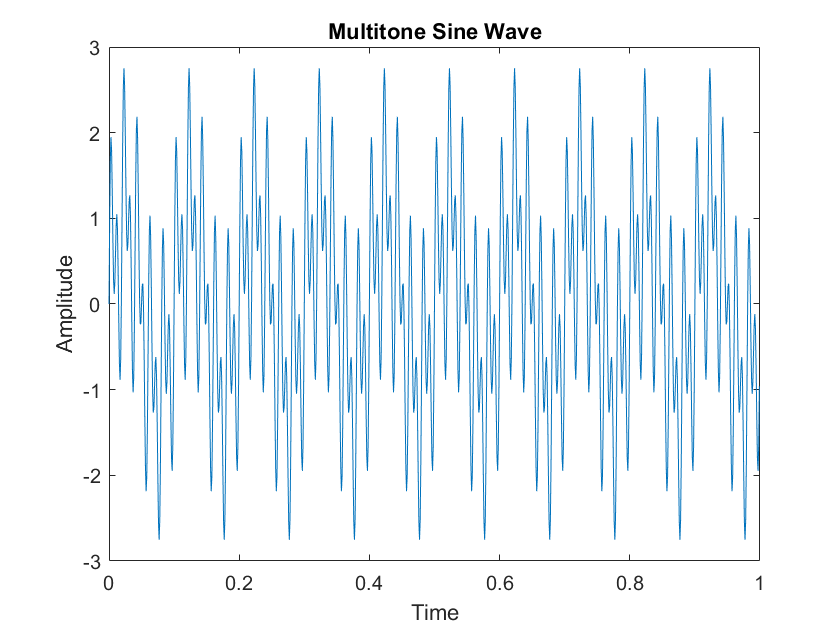

fs = 1000; % Sampling frequency (Hz) (Given)
step = 1/fs; % Incremental Step
timeDuration = 1; % Total time duration of sine wave (Given)
t = (0:step:timeDuration-1/fs); % Time interval 
f1 = 10; % Frequency (Hz) (Given)
f2 = 50;
f3 = 100;

sineWave_1 = sin(2*pi*f1*t);
sineWave_2 = sin(2*pi*f2*t);
sineWave_3 = sin(2*pi*f3*t);

multitone_sinewave = sineWave_1 + sineWave_2 + sineWave_3;
plot_signal(t, multitone_sinewave,'Time', 'Amplitude', ['Multitone Sine Wave']); % Plotting time domain plot

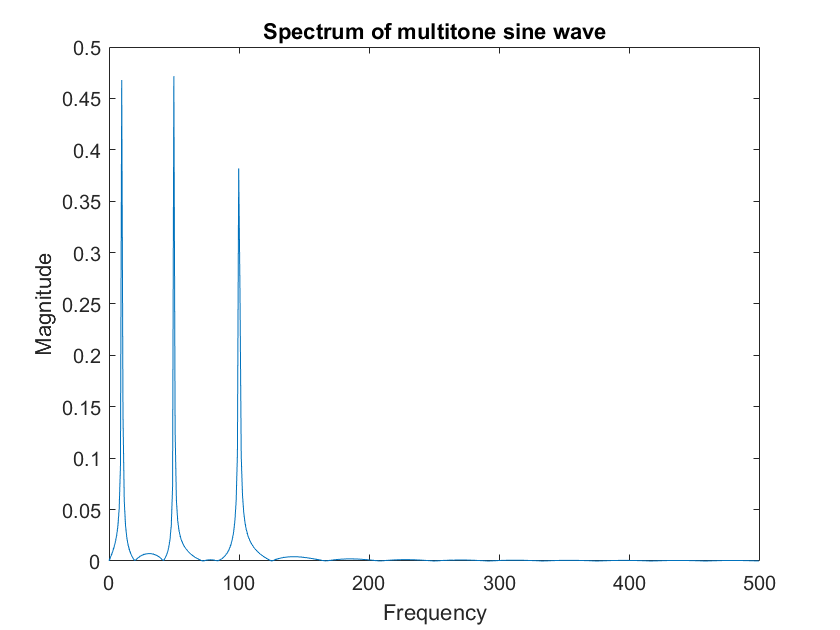

plot_spectrum(multitone_sinewave, fs, 'Spectrum of multitone sine wave');

## C. Generation of a non-stationary multitone sine wave and its spectrum

- Generate a non-stationary multitone sine wave made of different combinations of 10, 50 and 100 Hz components. 

- Generate the frequency spectrum taking the whole signal at once and taking each stationary part of the signal individually. Record your observations on the spectrum obtained by using the whole signal, the stationary parts individually and the limitations of Fourier Transform when we consider the whole non-stationary speech signal, even though the shape might imply otherwise.

### Theory:

To generate a non-stationary wave, we need to make sure that frequency is changing with time. Here what we do is that, for each sub-interval, we use different sine waves and multitone sine waves of different frequencies. This ensures that the final signal produced is a non-stationary signal, as along the frequency spectrum, the frequency is not constant with respect to time. The different time intervals are however stationary in nature so we can do frequency analysis over these regions.

Mathematically given as:

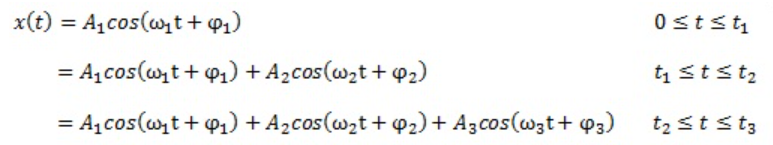

Here A1 = A2 = A3 = 1, $\omega_1 =10\;\textrm{Hz}$, $\omega_2 =50\;\textrm{Hz}$, $\omega_3 =100\;\textrm{Hz}$, $\varphi_1 =\varphi_{2\;} =\varphi_3 =0$

### Procedure:

We create non-stationary wave by combinations of different sinewaves (of different frequencies) which change throughout the time duration. Here we are having 

- sinewave of 10 Hz from 0-0.2 sec 

- summation of sinwaves of 10 Hz and 50 hz from 0.2 - 0.5 sec

- summation of sinewaves of 10, 50 and 100 Hz from 0.5 - 1 sec

Thus througout the whole time duration, we will see different waveforms along different sub-intervals. Frequency is changing along the time axis. 

We will take N-point FFTs of the 3 intervals separately to see the different frequency components present during a certain time interval. By taking these 3 intervals where stationarity is followed, we can see the frequency spectrum in a proper manner.

### Code and Plots:

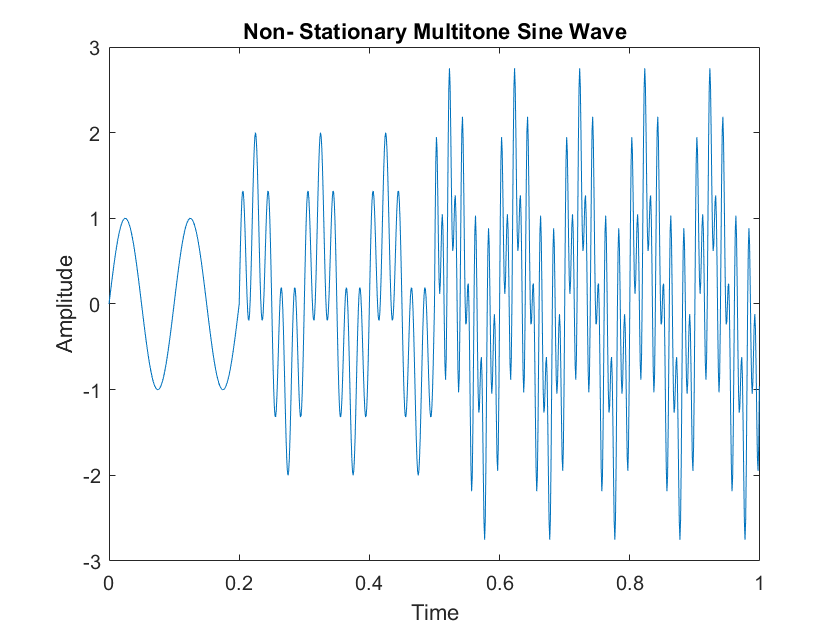

fs = 1000; % Sampling frequency (Hz) (Given)
step = 1/fs; % Incremental Step
timeDuration = 1; % Total time duration of sine wave (Given)
t = (0:step:timeDuration-1/fs); % Time interval 
f1 = 10; % Frequency (Hz) (Given)
f2 = 50;
f3 = 100;

sineWave_1 = sin(2*pi*f1*t);
sineWave_2 = sin(2*pi*f2*t);
sineWave_3 = sin(2*pi*f3*t);

z1 = sineWave_1 + sineWave_2;
z2 = sineWave_1 + sineWave_2 + sineWave_3;

non_stationary_wave = [sineWave_1(1:200) z1(201:500) z2(501:1000)];

plot_signal(t, non_stationary_wave,'Time', 'Amplitude', ['Non- Stationary Multitone Sine Wave']); % Plotting time domain plot

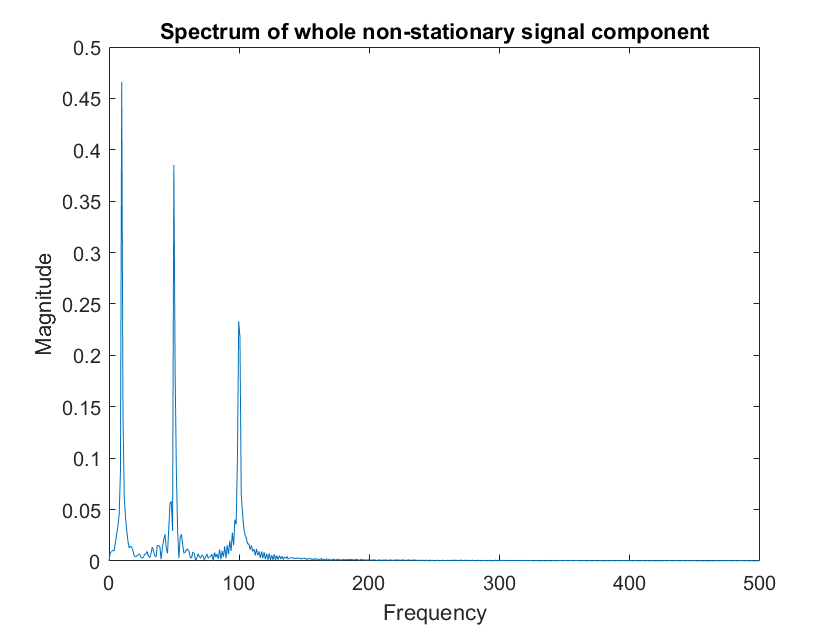

plot_spectrum(non_stationary_wave, fs, 'Spectrum of whole non-stationary signal component');

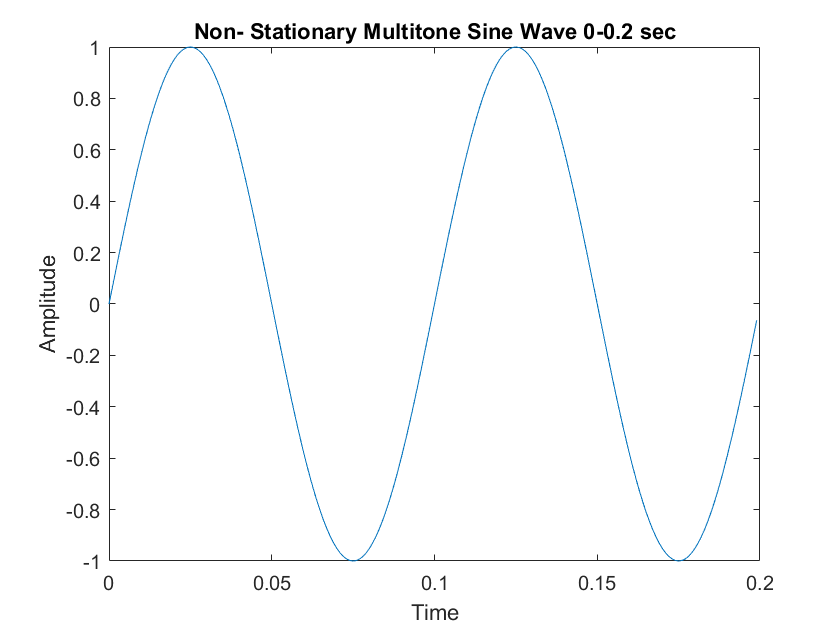

plot_signal(t(1:200), non_stationary_wave(1:200),'Time', 'Amplitude', ['Non- Stationary Multitone Sine Wave 0-0.2 sec']); % Plotting time domain plot

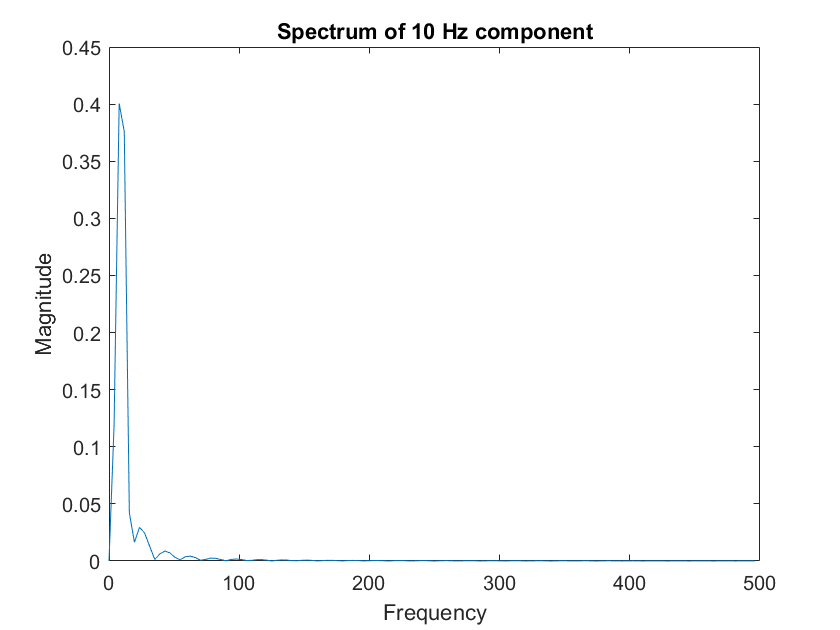

plot_spectrum(non_stationary_wave(1:200), fs, 'Spectrum of 10 Hz component');

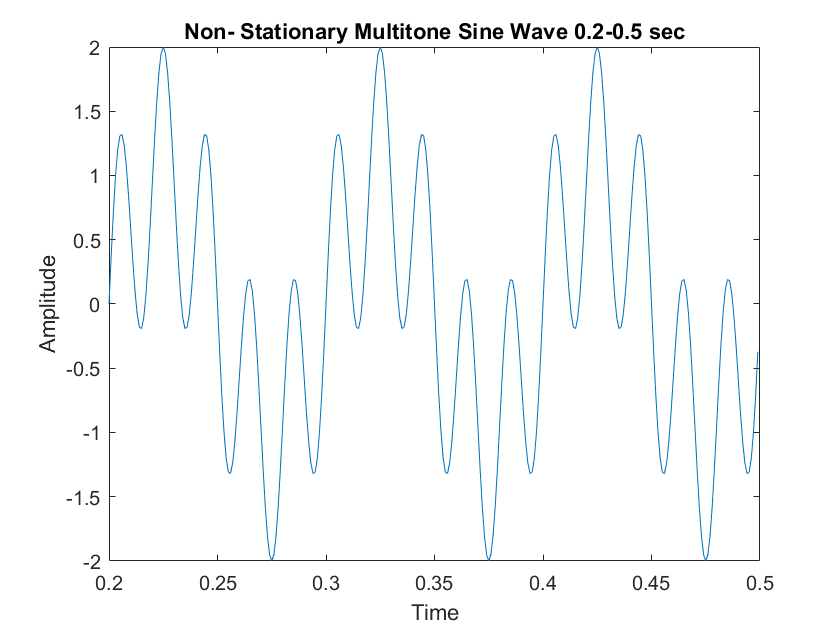

plot_signal(t(201:500), non_stationary_wave(201:500),'Time', 'Amplitude', ['Non- Stationary Multitone Sine Wave 0.2-0.5 sec']); % Plotting time domain plot

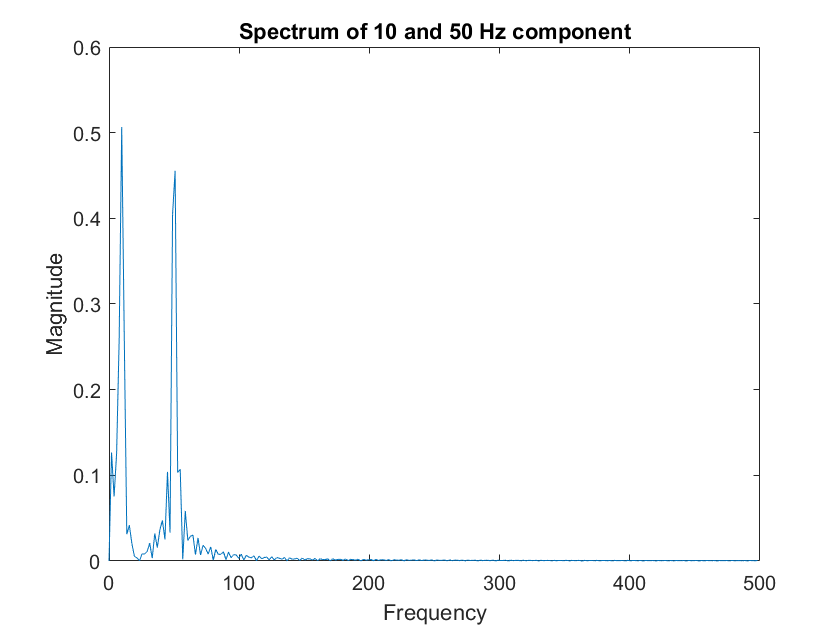

plot_spectrum(non_stationary_wave(201:500), fs, 'Spectrum of 10 and 50 Hz component');

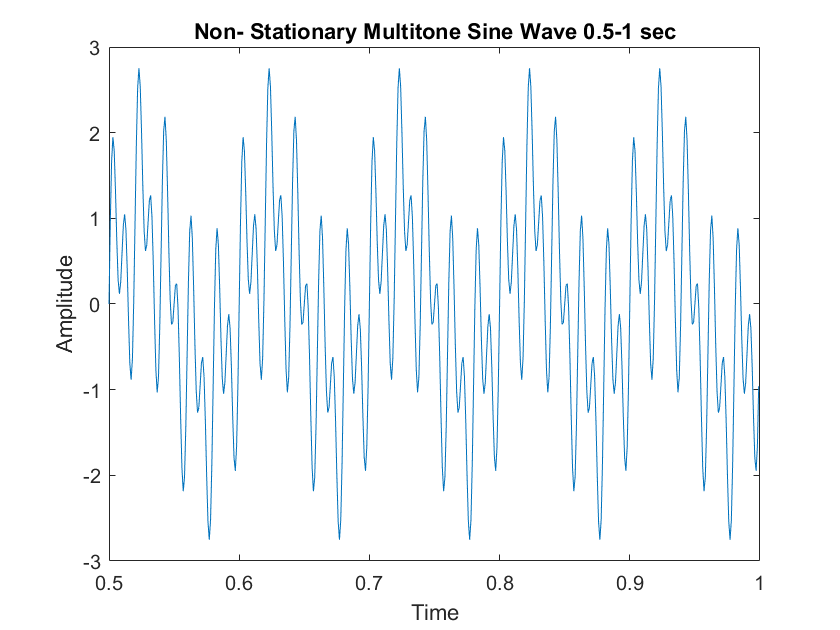

plot_signal(t(501:1000), non_stationary_wave(501:1000),'Time', 'Amplitude', ['Non- Stationary Multitone Sine Wave 0.5-1 sec']); % Plotting time domain plot

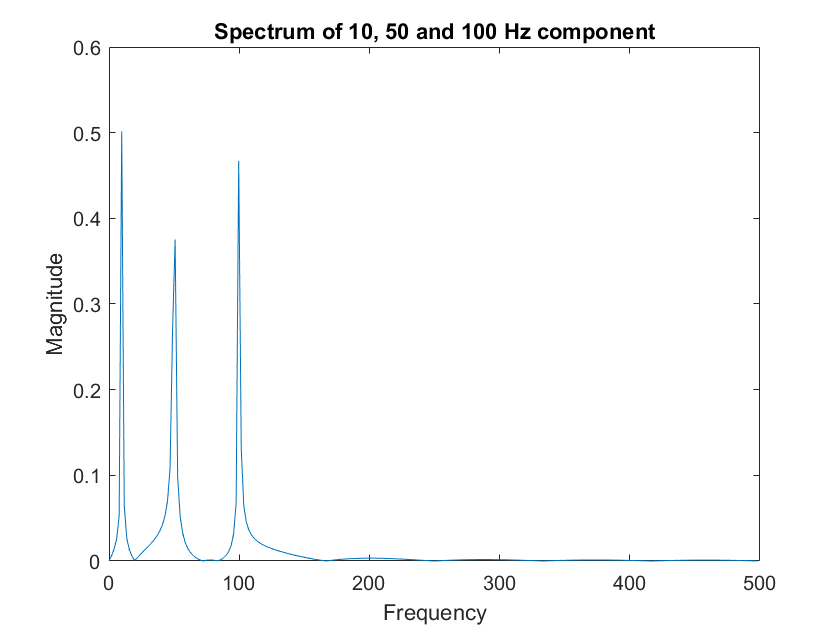

plot_spectrum(non_stationary_wave(501:1000), fs, 'Spectrum of 10, 50 and 100 Hz component');

### Observations:

When we take the spectrum of the whole signal, i.e. it is a non-stationary wave as a whole, the frequencies of all the components(10 Hz, 50 Hz and 100 Hz) are present in the spectrum, however we have no information regarding when these frequency components actually take place.

When we split the whole signal into segments of stationary parts, what we see is that in each segment there is a different frequency spectrum in the given interval. This shows us that the frequency spectrum does change with respect to time but when we take the whole signal we are not able to notice this information The frequency components are changing with time hence we see that this wave is a non-stationary wave.

If we did'nt know before-hand that this is a non-stationary wave, and checked the entire spectrum, we would not be able to find out if it is stationary or non-stationary. The spectrum is plotted by assuming the given waveform as stationary always, even if the waveform is infact non-stationary. Only by taking intervals of stationarity we are able to observe that the frequency is infact changing with time. This is the limitation of the fourier transform.

We could use spectrogram instead, where the frequency is shown in one axis and time is shown in the other axis.

## D. Plotting waveform and spectra of speech signal. 

- Record the phrase ‘Sakshaat Speech Processing’ and save it in a .wav file. Now, (re)sample the speech signal to 8kHz and plot the speech signal. 

- Compute and plot the spectrum of the different categories of sounds present in the recorded speech file. Inspect the spectral properties of sounds belonging to different categories, and comment on the nature of the whole speech signal.

### Theory:

A speech signal is different from convention synthetic signals, as it is non-stationary in nature and there are many frequency components and that too in smaller time intervals. The many frequency contents change continuosly with time. When the phrase "Sakshaat Speech Processing" is said, we observe that there are many frequency components as we go along taking spectrums of the non-stationary segments.

### Procedure:

First we record the phrase "Sakshaat Speech Processing" using a recorder (audacity, wavesurfer can be used to do this). Clip the unnecessary silence and read this wave file. Resample this read wavefile to 8000 Khz and again read the wave file. Take only the left channel of this wave file to do the necessary time domain plots and frequency domain plots. 

We plot the speech waveform along time domain and frequency domain, and find the sounds that are present throughout this waveform and plot  the spectrum of these categories of sounds and analyse the spectral properties. The categories of sounds present in this phrase are:

- Fricatives/Sibilants

- Vowels

- Semi-Vowels

- Affricates 

- Plosives

### Code and Plots:

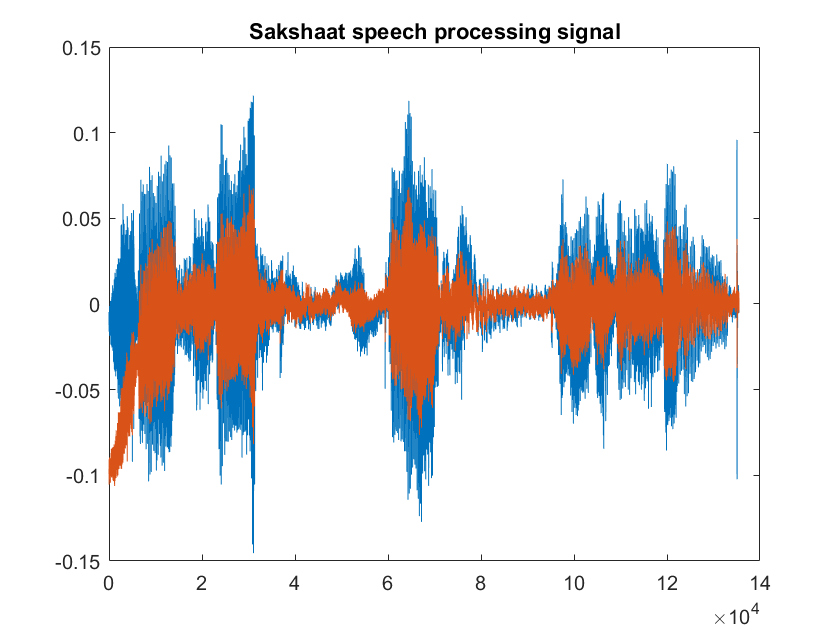

[y,fs]=audioread('sakshaatSpeechProcessing.wav'); 
audiowrite('sakshaatSpeechProcessing8000.wav',y,8000);

[y,fs]=audioread('sakshaatSpeechProcessing8000.wav'); 

plot(y);
title("Sakshaat speech processing signal");

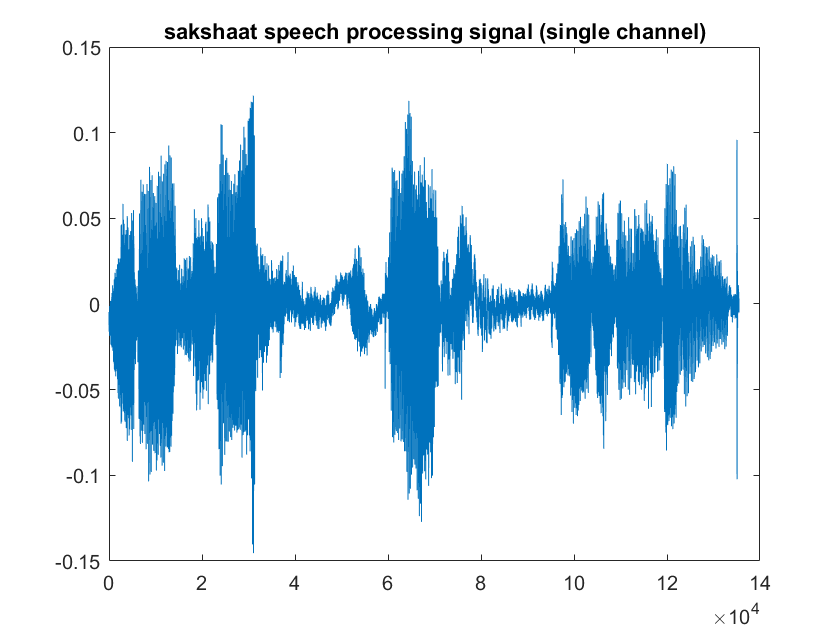

left = y(:,1);

plot(left)
title("sakshaat speech processing signal (single channel)");

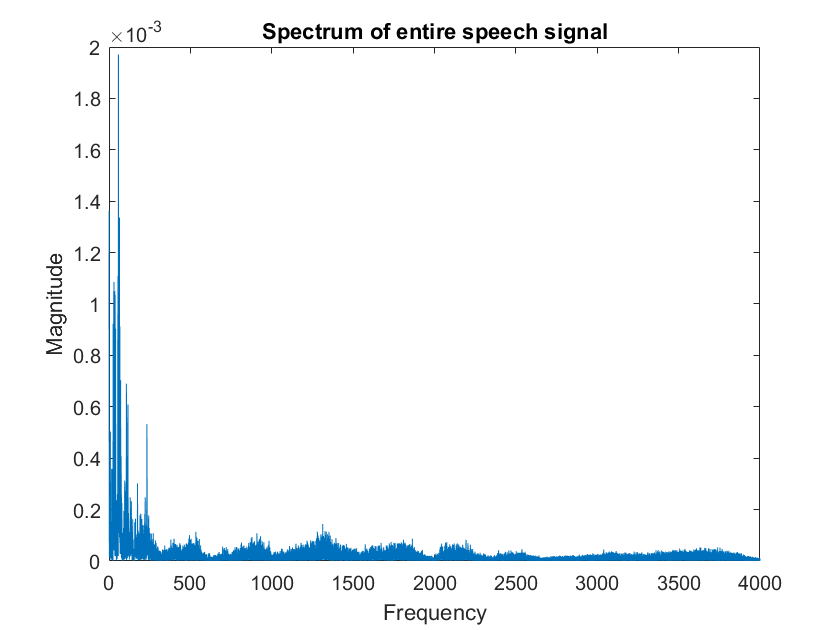

% spectrum of entire speech signal
plot_spectrum(left, 8000, 'Spectrum of entire speech signal');

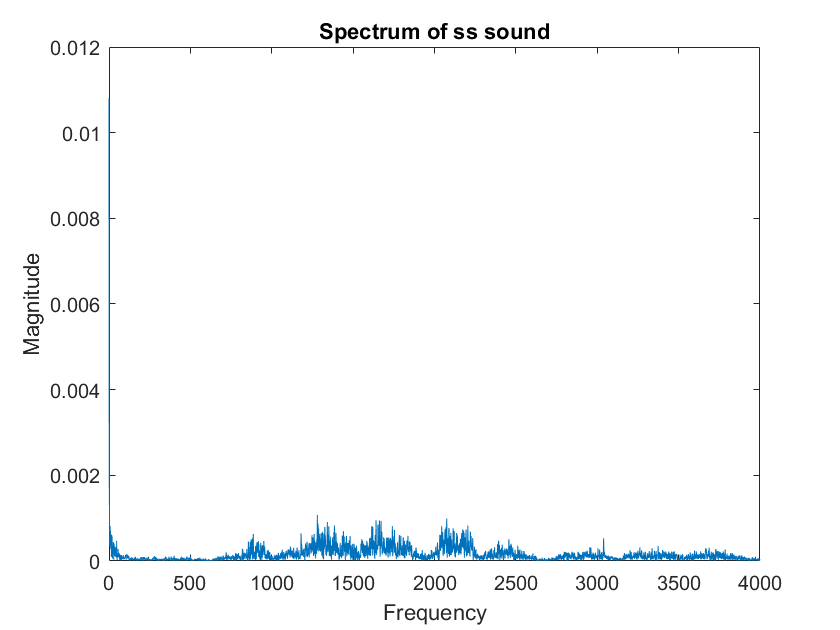


%ss sound (Fricative) (sibilant)
plot_spectrum(left(1:6281), 8000, 'Spectrum of ss sound');

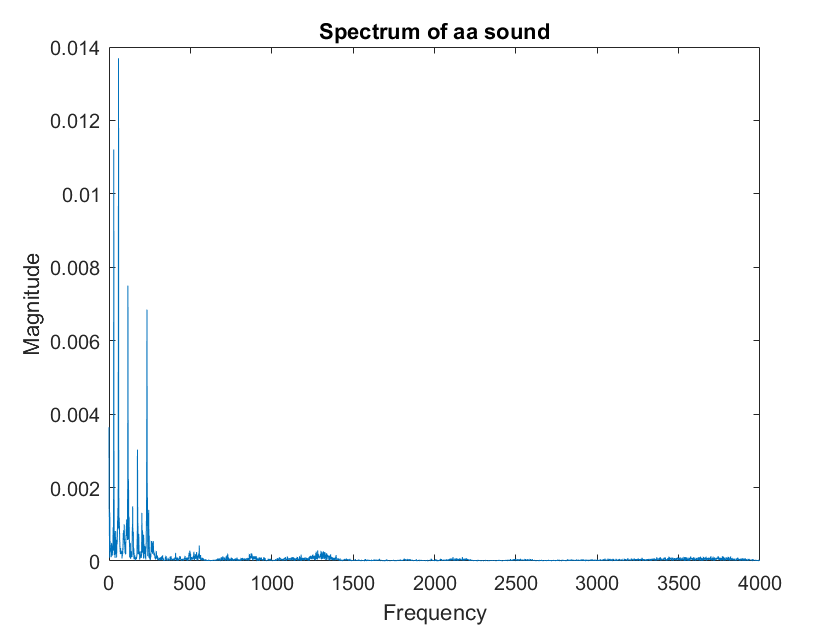

%aa sound (Vowel)
plot_spectrum(left(6281: 14440), 8000, 'Spectrum of aa sound');

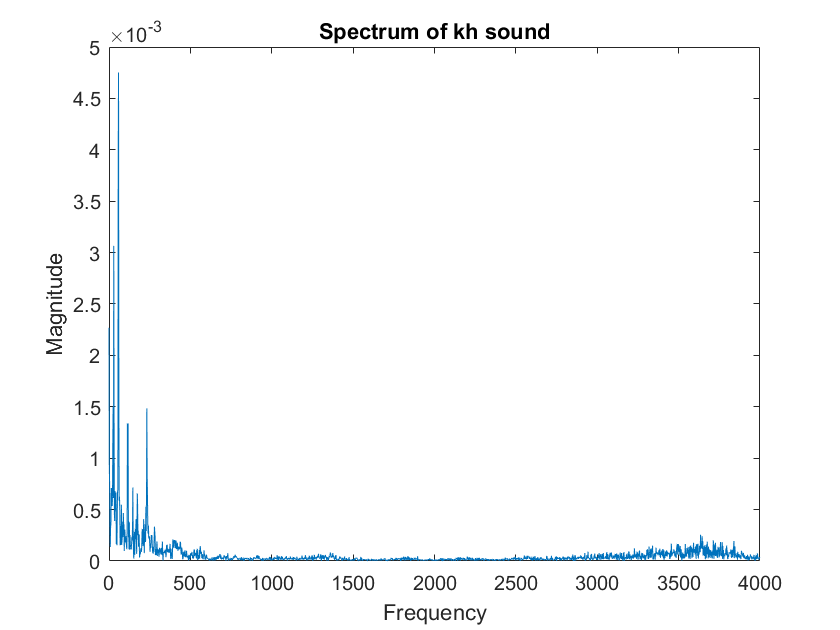

%kh sound (UA)
plot_spectrum(left(14440: 17783), 8000, 'Spectrum of kh sound');

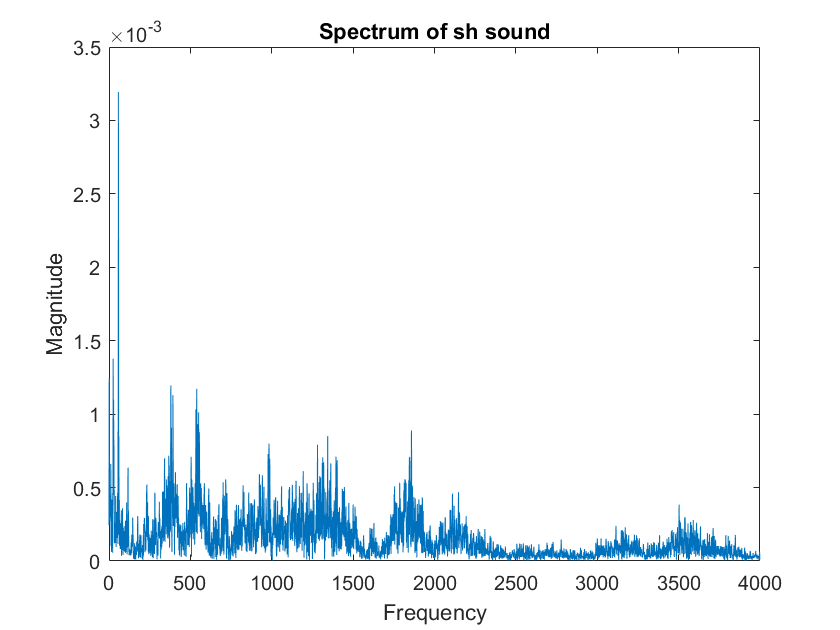

%sh sound (Fricative) (sibilant)
plot_spectrum(left(17783: 22887), 8000, 'Spectrum of sh sound');

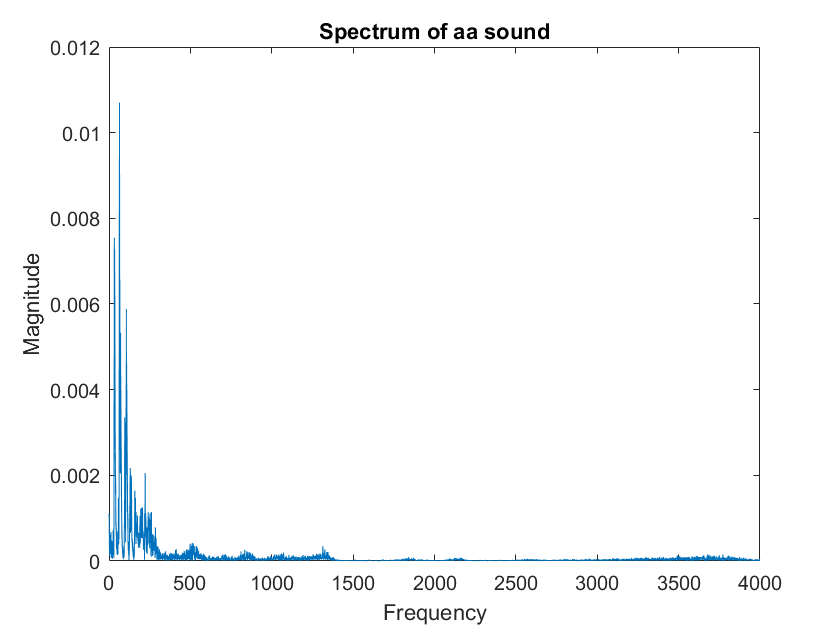

%aa sound (Vowel)
plot_spectrum(left(22887: 31495), 8000, 'Spectrum of aa sound');

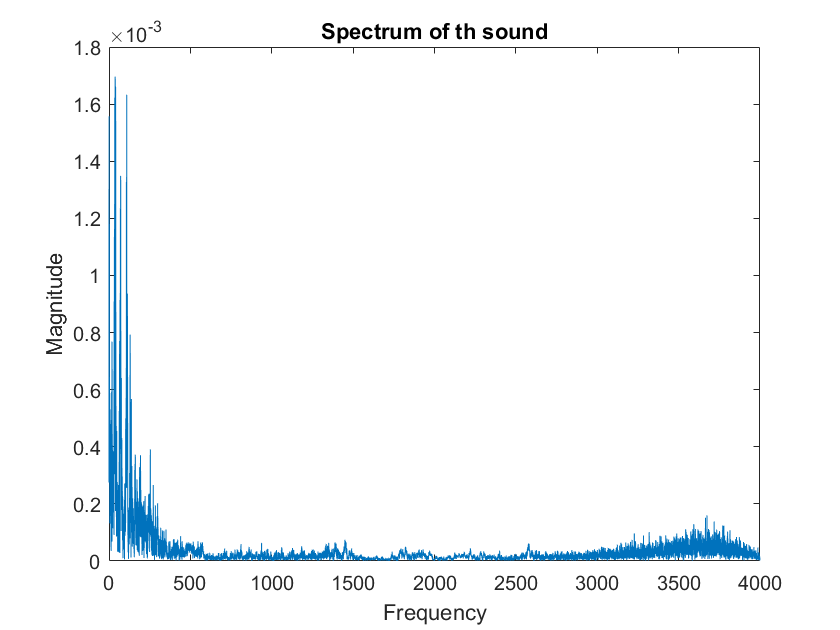

%th sound (UA)
plot_spectrum(left(31495: 41750), 8000, 'Spectrum of th sound');

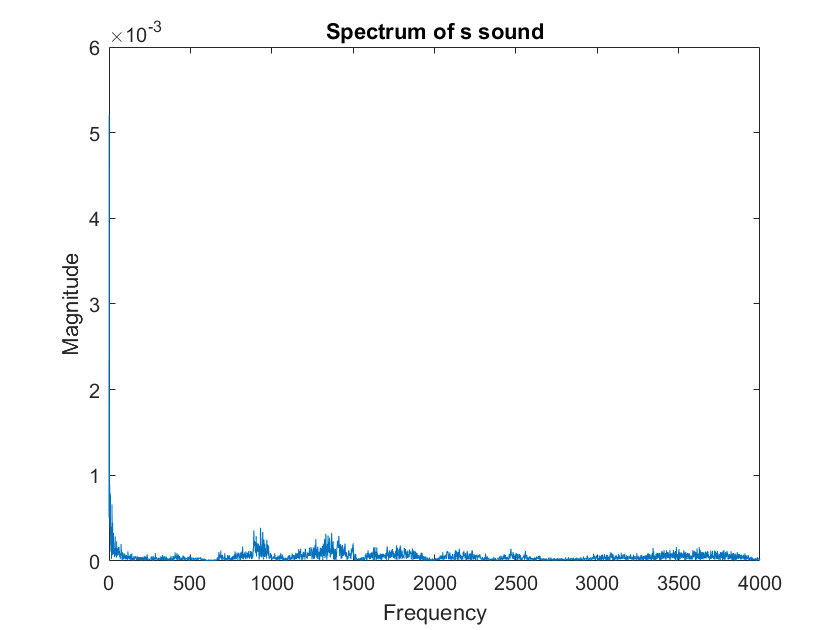

%s sound (Fricative) (sibilant)
plot_spectrum(left(49534: 57360), 8000, 'Spectrum of s sound');

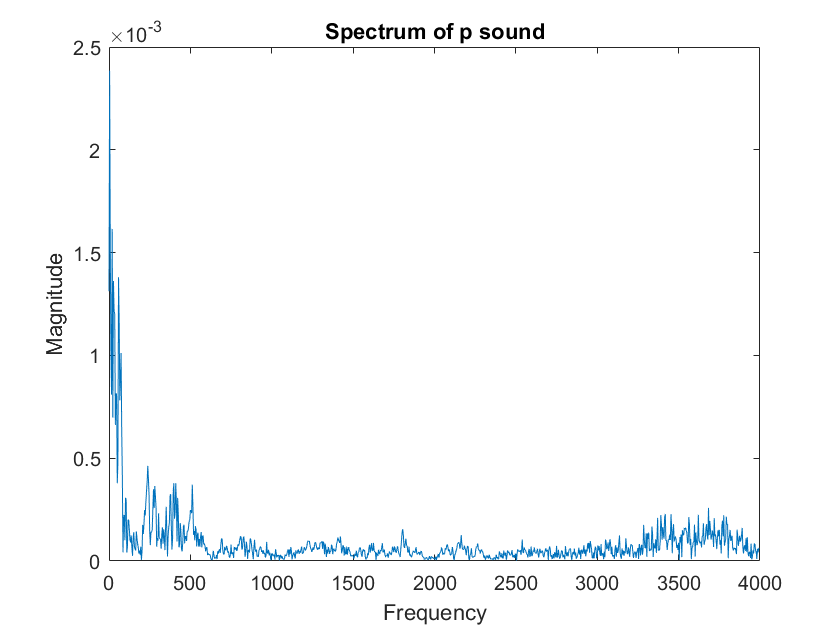

%p sound (UU)
plot_spectrum(left(58506: 60180), 8000, 'Spectrum of p sound');

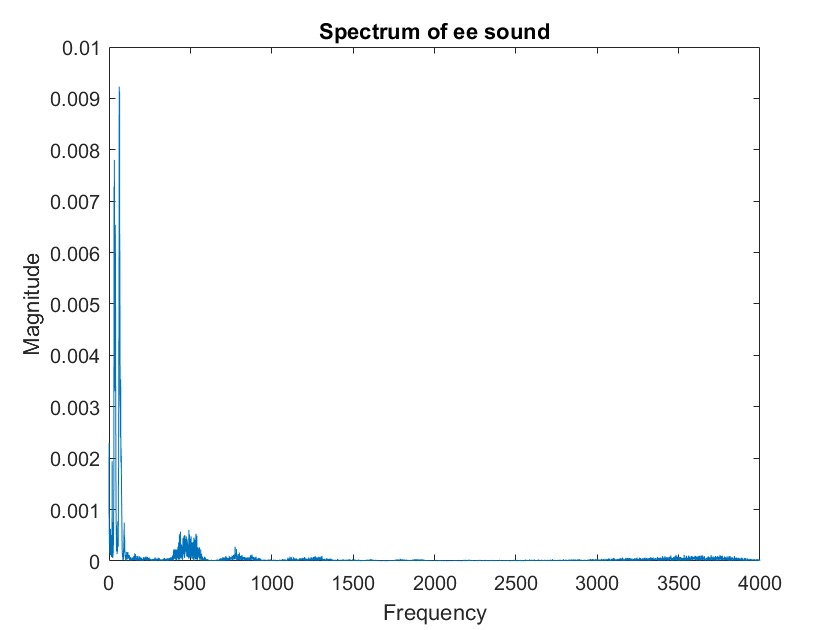

%ee sound (Vowels)
plot_spectrum(left(60180: 70862), 8000, 'Spectrum of ee sound');

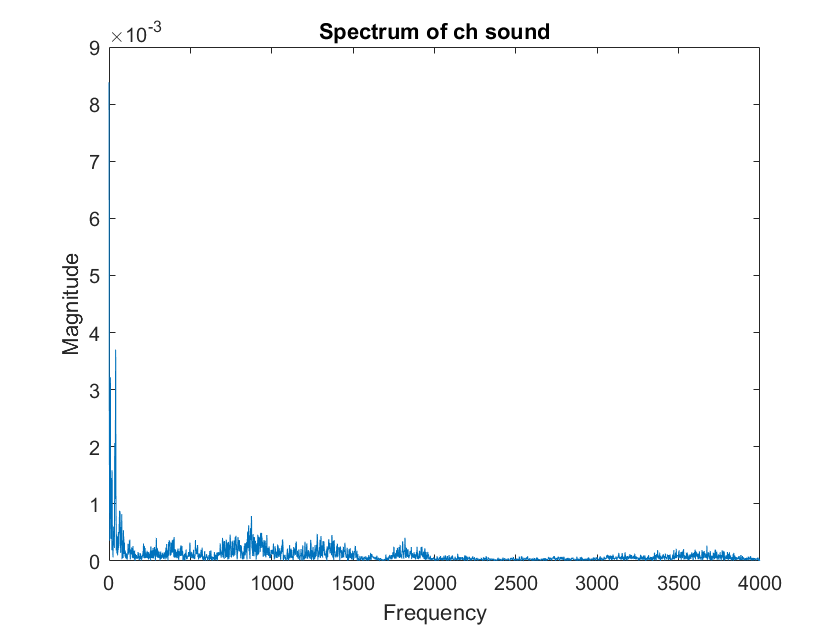

%ch sound (affricate)
plot_spectrum(left(74391: 79106), 8000, 'Spectrum of ch sound');

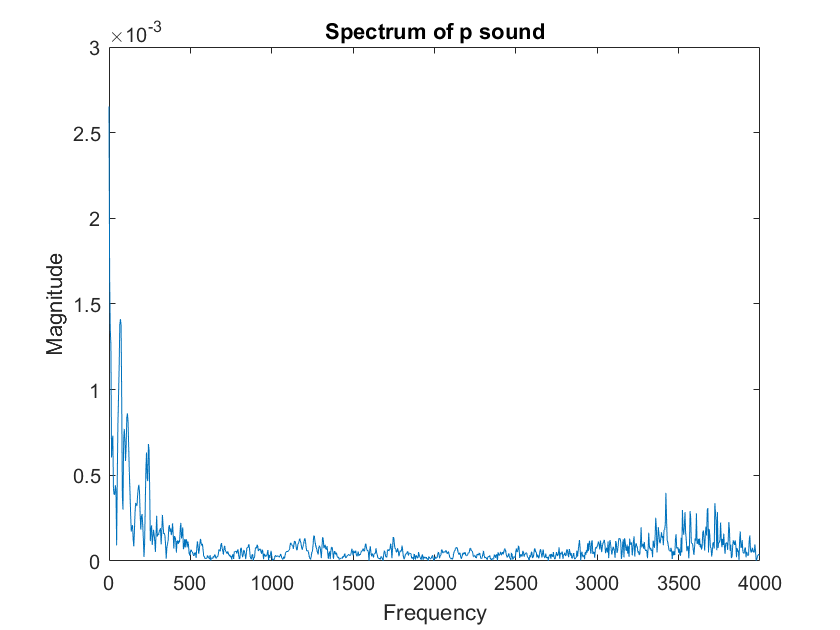

%p sound (UU)
plot_spectrum(left(94679: 95945), 8000, 'Spectrum of p sound');

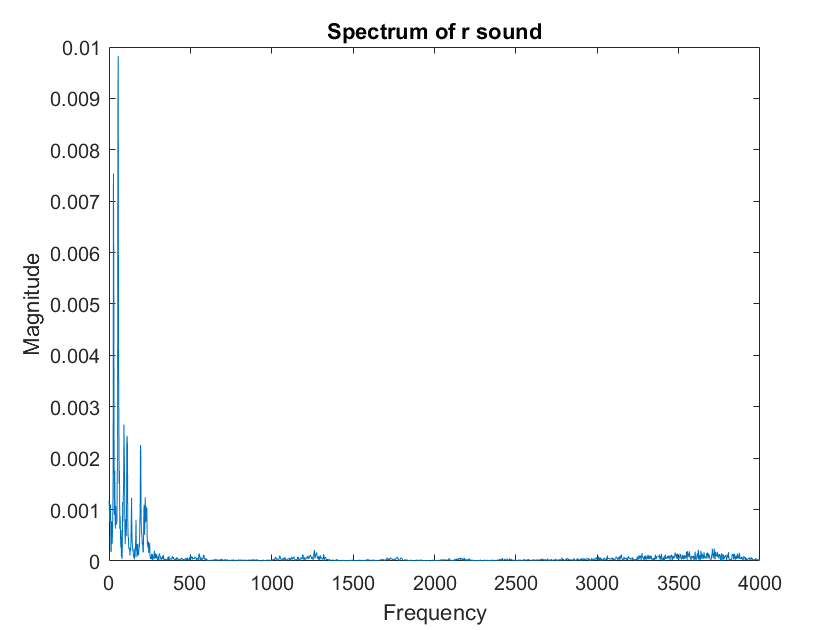

%r sound (semi vowel)
plot_spectrum(left(96315: 99256), 8000, 'Spectrum of r sound');

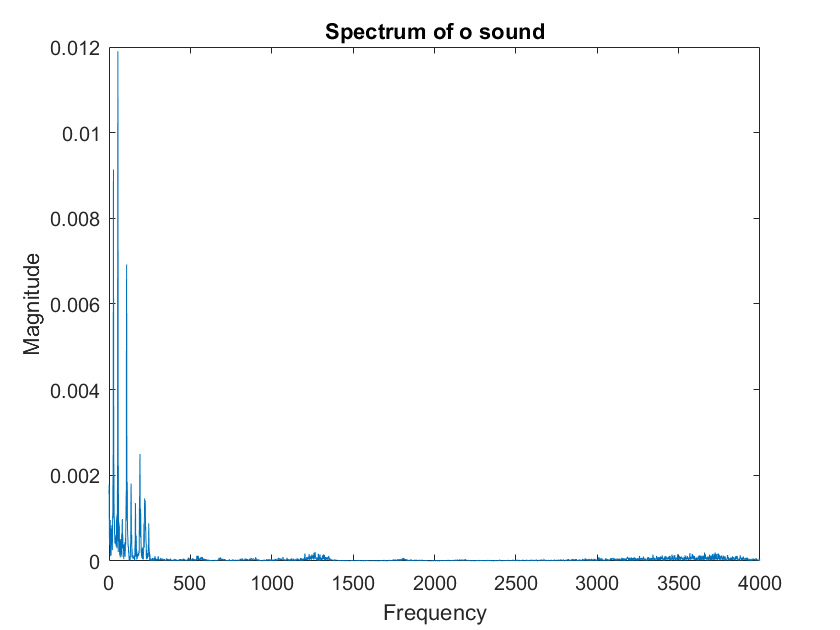

%o sound (vowels)
plot_spectrum(left(99256: 103694), 8000, 'Spectrum of o sound');

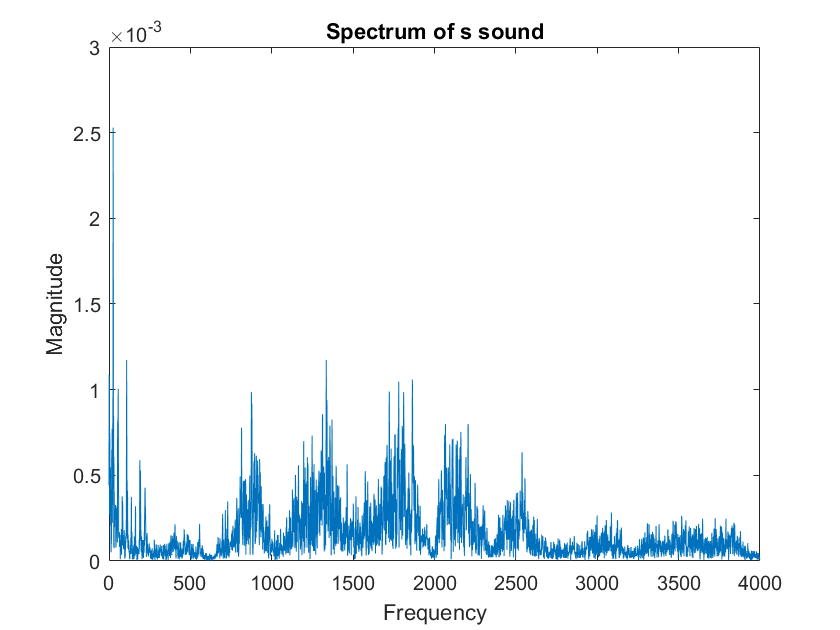

%s sound (fricatives) (sibilant)
plot_spectrum(left(103875: 108977), 8000, 'Spectrum of s sound');

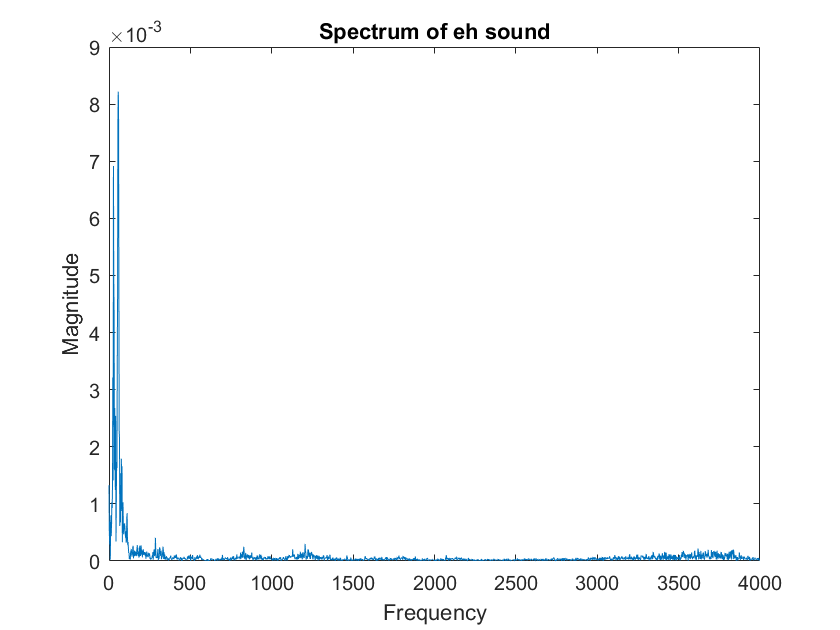

%eh sound (vowel)
plot_spectrum(left(108977: 111918), 8000, 'Spectrum of eh sound');

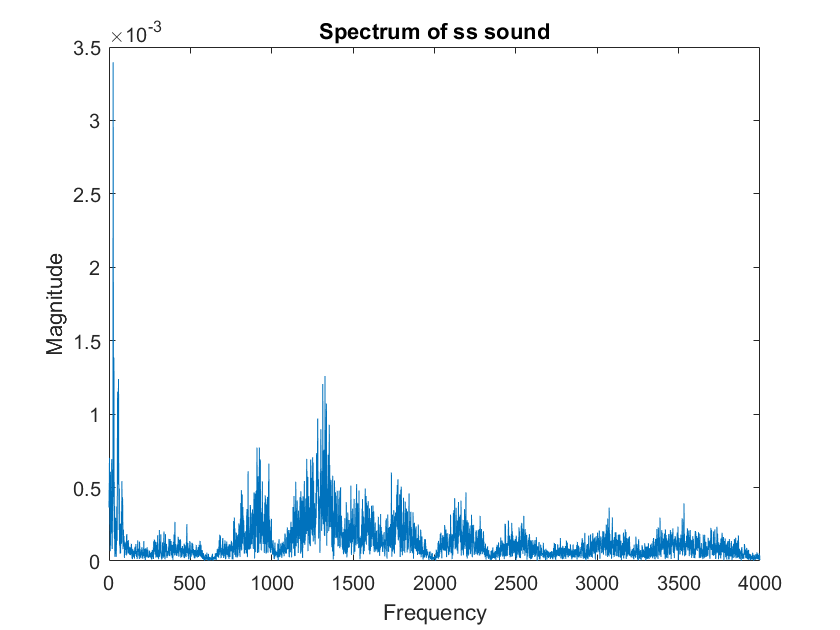

%ss sound (fricative) (sibilant)
plot_spectrum(left(112607: 119060), 8000, 'Spectrum of ss sound');

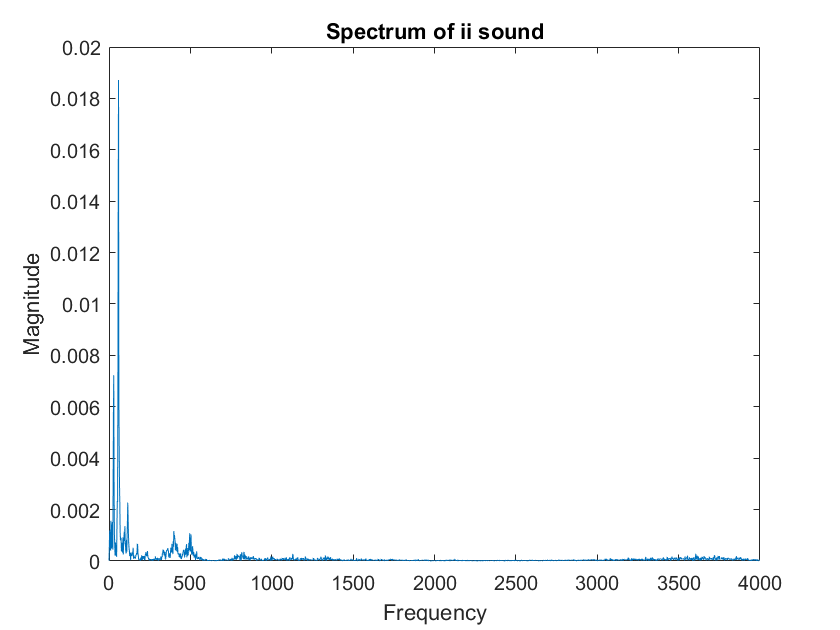

%ii sound (vowel)
plot_spectrum(left(119500: 122568), 8000, 'Spectrum of ii sound');

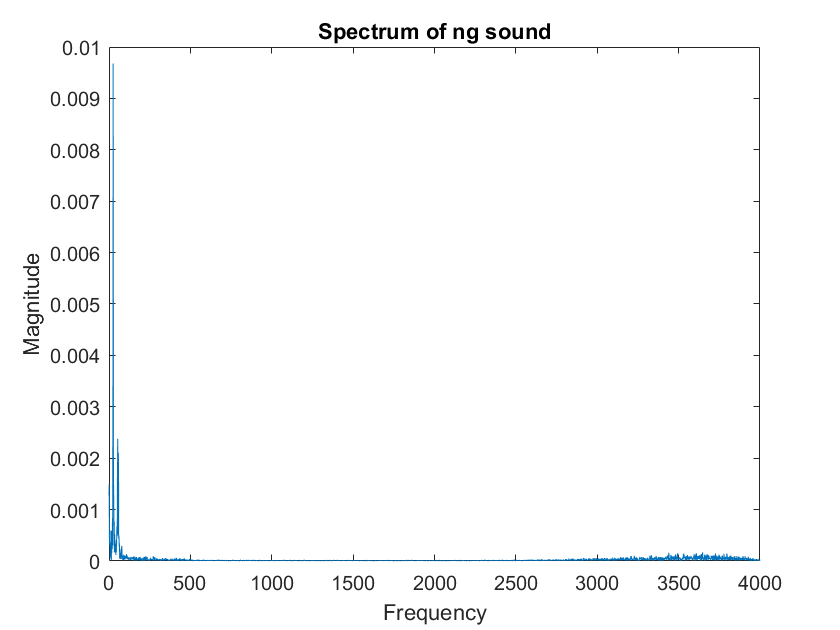

%ng sound (affricate, nasal)
plot_spectrum(left(127223: 132645), 8000, 'Spectrum of ng sound');

### Observations:

There are these categories of speech sounds present:

- Fricatives/Sibilants: We observe many high frequency contents in the spectrum of varying magnitudes. High frequencies are dominating here

- Vowels (long and short vowels): We observe that at low frequencies, there is considerable magnitude and at higher frequencies there is less magnitude. Low frequencies are dominated in this case.

- Semi Vowels: Spectrum is very similar to vowels

- UU (plosives): Fluctuating magnitudes along a wide range of frequencies

- UA (plosives): High magnitudes at low frequencies, wide range of frequencies covered

- Affricates: Spectrum similar to fricatives but with lesser magnitude

The nature of the whole speech signal is non-stationary which makes frequency analysis difficult by only using fourier transform.

## **Function Definitions:**

function plot_spectrum(x, fs, title_name)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    X = abs(fft(x, n));
    X = X/n;
    plot(f(1:floor(n/2)),X(1:floor(n/2)));
    title(title_name)
    xlabel('Frequency')
    ylabel('Magnitude')
end

function plot_signal(x, y, x_label, y_label, title_name)
    plot(x, y);
    xlabel(x_label);
    ylabel(y_label);
    title(title_name);
end